# 清空环境

clc
clear
warning off

## 遗传算法参数

% 对于遗传算法 + 非线性非线性规划的寻优组合， 效果显然好于单纯的遗传算法。
maxgen = 30;                         % 进化代数
sizepop = 100;                       % 种群规模
pcross = 0.6;                        % 交叉概率
pmutation = 0.01;                    % 变异概率
lenchrom = [1 1 1 1 1];              % 变量字串长度
bound=[0 0.9*pi;
       0 0.9*pi;
       0 0.9*pi;
       0 0.9*pi;
       0 0.9*pi];                    % 变量范围

## 个体初始化

individuals = struct('fitness', zeros(1, sizepop), 'chrom', []);  % 种群结构体
avgfitness =[];                                                   % 种群平均适应度
bestfitness = [];                                                 % 种群最佳适应度
bestchrom = [];                                                   % 适应度最好染色体
% 初始化种群
for i = 1 : sizepop
    individuals.chrom(i, :) = Code(lenchrom, bound);              % 随机产生个体
    x = individuals.chrom(i, :);
    individuals.fitness(i) = fun(x);                              % 个体适应度
end

% 找最好的染色体
[bestfitness, bestindex] = min(individuals.fitness);
bestchrom = individuals.chrom(bestindex, :);      % 最好的染色体
avgfitness = sum(individuals.fitness) / sizepop;  % 染色体的平均适应度
% 记录每一代进化中最好的适应度和平均适应度
trace = [];

## 进化开始

for i = 1:maxgen
    
    % 选择操作
    individuals = Select(individuals,sizepop);
    avgfitness = sum(individuals.fitness) / sizepop;
    % 交叉操作
    individuals.chrom = Cross(pcross, lenchrom, individuals.chrom, sizepop, bound);
    % 变异操作
    individuals.chrom = Mutation(pmutation, lenchrom, individuals.chrom, sizepop, [i maxgen], bound);
    
    % 该实现的非线性规划就体现于此
    % 每隔一段时间，利用非线性规划寻优更新染色体
    if mod(i, 10) == 0
        individuals.chrom = nonlinear(individuals.chrom, sizepop);
    end
    
    % 计算适应度
    for j = 1:sizepop
        x = individuals.chrom(j, :);
        individuals.fitness(j) = fun(x);
    end
    
    % 找到最小和最大适应度的染色体及它们在种群中的位置
    [newbestfitness, newbestindex] = min(individuals.fitness);
    [worestfitness, worestindex] = max(individuals.fitness);
    % 代替上一次进化中最好的染色体
    if bestfitness > newbestfitness
        bestfitness = newbestfitness;
        bestchrom = individuals.chrom(newbestindex, :);
    end
    individuals.chrom(worestindex, :) = bestchrom;
    individuals.fitness(worestindex) = bestfitness;
    
    avgfitness = sum(individuals.fitness) / sizepop;
    
    % 这个trace在这儿每次都要改变储存空间，肯定是不够优雅和快速的
    trace = [trace; avgfitness bestfitness worestfitness]; % 记录每一代进化中最好的适应度和平均适应度
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

% 进化结束

## 结果显示

figure
[r, c]=size(trace);
plot((1:r)', trace(:, 1), 'g-', (1:r)', trace(:, 2),'b--', (1:r), trace(:, 3), 'r');
title(['函数值曲线  ' '终止代数＝' num2str(maxgen)], 'fontsize', 12);
xlabel('进化代数', 'fontsize', 12); ylabel('函数值','fontsize', 12);
legend('各代平均值', '各代最佳值', '各代最差值','fontsize', 12);
ylim([1 10])
disp('函数值        变量');

函数值        变量


% 窗口显示
disp([bestfitness x]);

    2.0000    1.5708    1.5708    1.5708    1.5708    1.5708



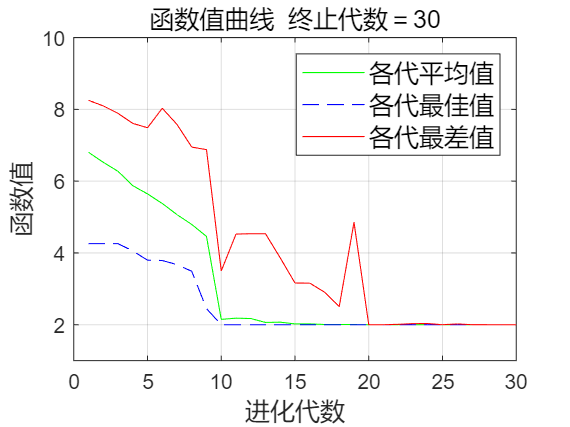

grid on